clc; clear;

 Read image

image= imread('Y16.jpg');

Change to binary image

bw = im2bw(image,0.60);
label = bwlabel(bw);

Measure solidity and area of the tumor

stats = regionprops(label, 'Solidity', 'Area');
density = [stats.Solidity];
area = [stats.Area];

Filter out areas of low density, only possible tumors should be left

denseArea = density > 0.25;

Find largest occurrence of acceptable density

largestArea = max(area(denseArea));

Locate tumor that will be outlined

tumorOutline = find(area == largestArea);
finalTumor = ismember(label, tumorOutline);
se = strel('diamond',5)

se = strel is a diamond shaped structuring element with properties:

      Neighborhood: [11×11 logical]
    Dimensionality: 2


finalTumor = imdilate(finalTumor,se);

Remove holes from the dilated tumor

[B,L]= bwboundaries(finalTumor,'noholes');

Plot final image

imshow(image,[]);

Outline the tumor

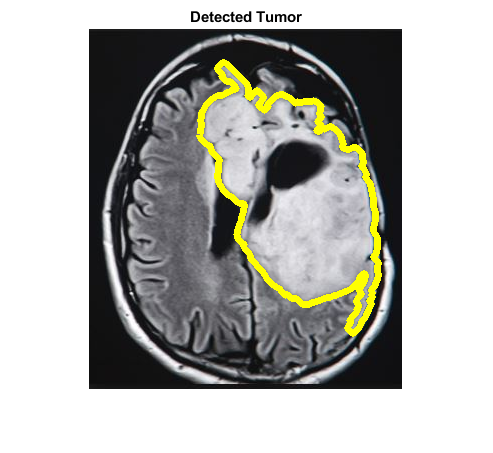

hold on
for i = 1:length(B)
    plot(B{i}(:,2),B{i}(:,1),'y','linewidth',5);
end
title('Detected Tumor');
hold off